# **Assignment:  Feature Extraction of CWRU Dataset**

**Student Number : 21700469**

**Name: Jinsu Yu**

**Given:  ****CWRU bearing dataset **

[https://engineering.case.edu/bearingdatacenter/download-data-file](https://engineering.case.edu/bearingdatacenter/download-data-file)

Classes:

-  Normal / Outer Race fault / Inner Race fault / Ball fault

**Instruction**

This Assignment is implementation a part of Feature Extration in  the literature 

- Rauber, T. W., de Assis Boldt, F., & Varejao, F. M. (2015, January). Heterogeneous Feature Models and Feature Selection Applied to Bearing Fault Diagnosis. *IEEE Transactions on Industrial Electronics*. Institute of Electrical and Electronics Engineers (IEEE).

**1. Extract and Analyze  Features**

**2. Compare  Features among different classes**

## Dataset

Sampling: 

- **Drive end bearing(12K): 12,000 samples/second**

Classes:

- Normal / Outer Race fault / Inner Race fault

- Each under 1HP load,  fault diameter of 0.007inches

Variables

- DE - drive end accelerometer data

- FE - fan end accelerometer data

- BA - base accelerometer data

- time - time series data

- RPM - shaft rpm during testing

### Drive End Bearing Experiment- 12K

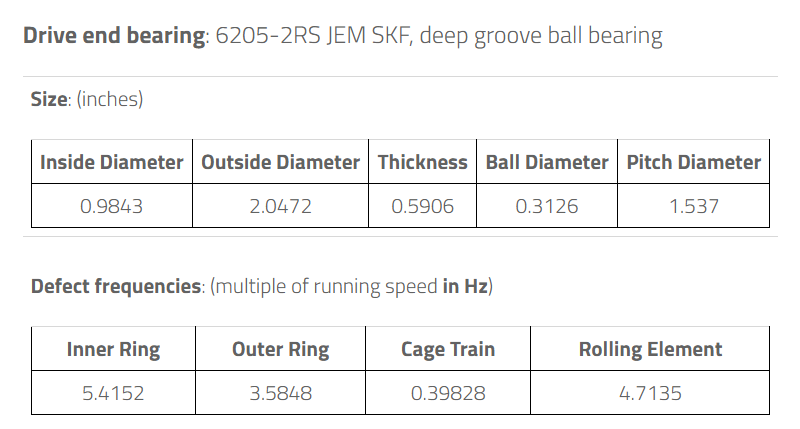

clear all; close all; clc;

%%% Load Dataset

load(fullfile('Assignment_FeatureExtraction_CWRU_data', 'normal_1hp.mat'))    %x098
load(fullfile('Assignment_FeatureExtraction_CWRU_data', 'outer_007_1hp.mat')) %x131
load(fullfile('Assignment_FeatureExtraction_CWRU_data', 'inner_007_1hp.mat')) %x106
load(fullfile('Assignment_FeatureExtraction_CWRU_data', 'ball_007_1hp.mat'))  %X119


BPFO_freq = 3.5848 * X131RPM / 60;
BPFI_freq = 5.4152 * X106RPM / 60;
BPFB_freq = 4.7135 * X119RPM / 60;

fs = 12000;

N_normal_DE = length(X098_DE_time)-1;
N_outer_DE = length(X131_DE_time);
N_inner_DE = length(X106_DE_time)-1;
N_ball_DE = length(X119_DE_time);

t_normal_DE = (0 : length(X098_DE_time)-1)/fs;
t_outer_DE = (0 : length(X131_DE_time))/fs;
t_inner_DE = (0 : length(X106_DE_time)-1)/fs;
t_ball_DE = (0 : length(X119_DE_time)-1)/fs;

Freq_normal_DE = 0 : fs/N_normal_DE : fs/2;
Freq_outer_DE = 0 : fs/N_outer_DE : fs/2;
Freq_inner_DE = 0 : fs/N_inner_DE : fs/2;
Freq_ball_DE = 0 : fs/N_ball_DE : fs/2;

X098_DE_freq = getFFT(X098_DE_time,N_normal_DE);
X131_DE_freq = getFFT(X131_DE_time,N_outer_DE);
X106_DE_freq = getFFT(X106_DE_time,N_inner_DE);
X119_DE_freq = getFFT(X119_DE_time,N_ball_DE);

## **Drive End Accelerometer Data Analysis Sequence**

• Time Statistical Features

• Frequency Statistical Features

• Plot FFT/PSD

• Envelop Extraction

• Plot  STFT of given signal

• Plot  Kurtogram

• Plot  Spectral Kurtosis

• Apply bandpass filtering 

• Compare analyzed features for each states

## **1. Class : Normal**

**: **Normal dataset. To compare with the defect dataset, the characteristics of the normal data are analyzed first.

**• Time-Domain Signal**

: Plot the raw normal data in the time domain.

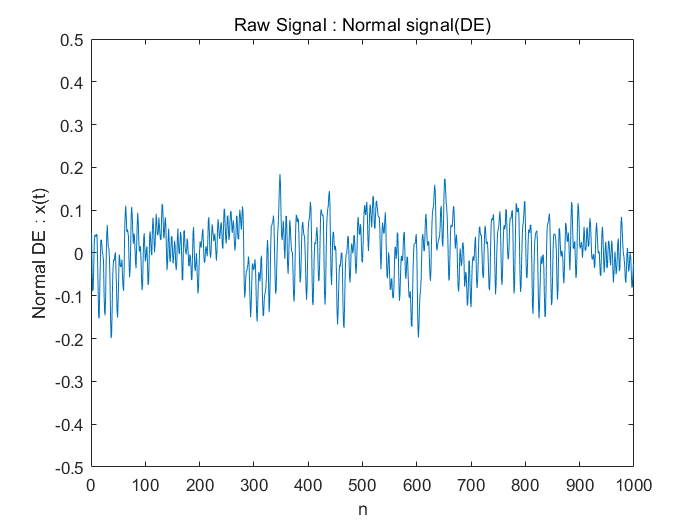

figure(1)

plot(X098_DE_time(1:1000));
% plot(t_normal_DE, X098_DE_time);
% xlim([0, 0.1]) / plot 0sec ~ 0.1sec

ylim([-0.5, 0.5])
title('Raw Signal : Normal signal(DE)'); 
xlabel('n'); ylabel('Normal DE : x(t)');

**• Time Statistical Features **

normal_time_DE = timeFeatures(X098_DE_time)

normal_time_DE = 1×10 table
      rms         sra         kv         sv        ppv        cf        if       mf        sf         kf    
    ________    ________    ______    ________    ______    ______    ______    _____    ______    _________

    0.066352    0.045547    2.9306    -0.17305    0.6634    5.2129    6.4686    7.594    1.2409    1.512e+05


**• Frequency Statistical Features **

normal_freq_DE = freqFeatures(X098_DE_freq)

normal_freq_DE = 1×3 table
        fc           rmsf          rvf    
    __________    __________    __________

    4.1544e-05    0.00018905    0.00018443


**• Plot FFT/PSD**

: The following graph is output to check what the main frequencies constituting the signal are, and to check what magnitude each frequency has.

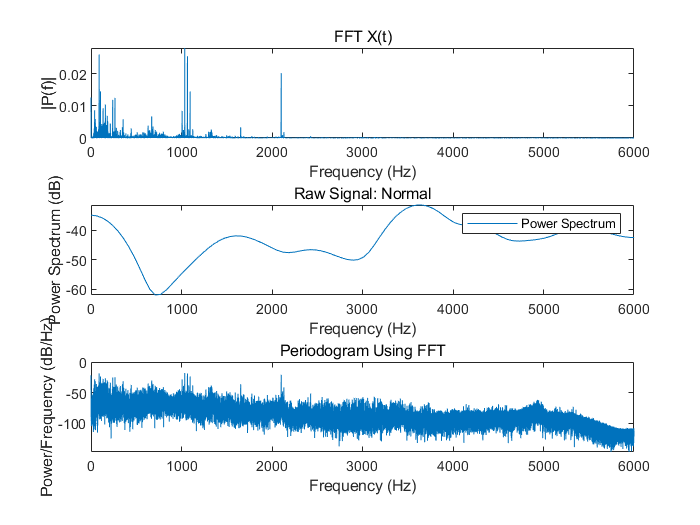

figure(2)

% FFT
subplot(3, 1, 1)
plot(Freq_normal_DE, X098_DE_freq) 
title('FFT X(t)')
xlabel('Frequency (Hz)')
ylabel('|P(f)|')

% Power Spectrum
subplot(3, 1, 2)
[pNormal, fpNormal] = pspectrum(X098_DE_time, N_normal_DE);
plot(fpNormal, 10*log10(pNormal))
xlim([0, 6000])
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Raw Signal: Normal')
legend('Power Spectrum')

% PSD
subplot(3, 1, 3)
normal_psdx = getPSD(X098_DE_time, N_normal_DE, fs);
plot(Freq_normal_DE, 10*log10(normal_psdx));
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')

Now zoom in the power spectrum of the raw signal in low frequency range to take a closer look at the frequency response at BPFO & BPFI & BPFB and its first several harmonics.

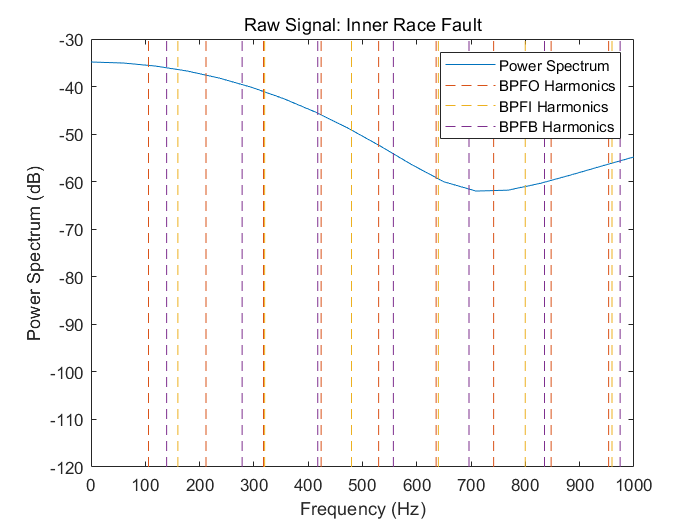

figure(3)

plot(fpNormal, 10*log10(pNormal))
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Raw Signal: Inner Race Fault')
legend('Power Spectrum', 'BPFO Harmonics', 'BPFI Harmonics', 'BPFB Harmonics')
xlim([0 1000])

No clear pattern is visible at BPFO&BPFI&BPFB and its harmonics. Frequency analysis on the raw signal does not provide useful diagnosis information.

--> Use Envelop Extraction

**• Envelop Extraction**

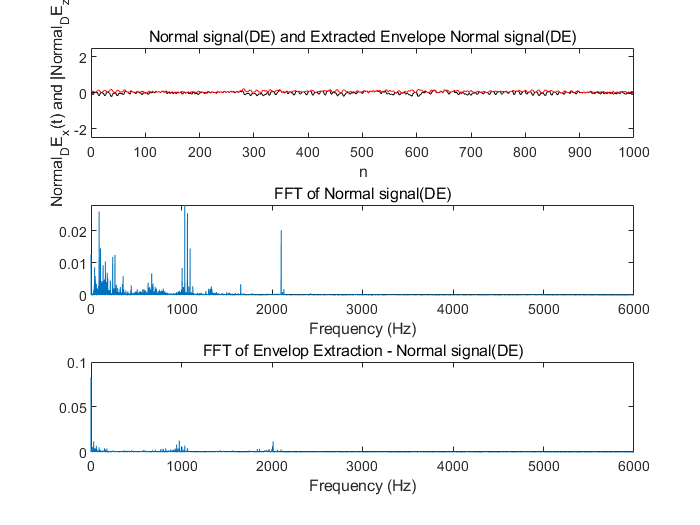

normal_envelop_extraction_DE = analyticSignal(X098_DE_time(1 : end-1));

figure(4)

subplot(3, 1, 1)
plot(X098_DE_time(1:1000), 'k'); hold on;
plot(abs(normal_envelop_extraction_DE(1:1000)), 'r');
ylim([-2.5, 2.5])
title('Normal signal(DE) and Extracted Envelope Normal signal(DE)'); 
xlabel('n'); ylabel('Normal_DE_x(t) and |Normal_DE_z(t)|');

subplot(3, 1, 2);
plot(Freq_normal_DE, X098_DE_freq); % X098_DE_freq = getFFT(X098_DE_time, N_normal_DE)
title('FFT of Normal signal(DE)'); xlabel('Frequency (Hz)')

subplot(3, 1, 3);
normal_envelop_fft_DE = getFFT(abs(normal_envelop_extraction_DE), N_normal_DE);
plot(Freq_normal_DE, normal_envelop_fft_DE);
title('FFT of Envelop Extraction - Normal signal(DE)'); xlabel('Frequency (Hz)')

Now zoom in the Envelope spectrum in low frequency range to take a closer look at the frequency response at BPFO & BPFI & BPFB and its first several harmonics.

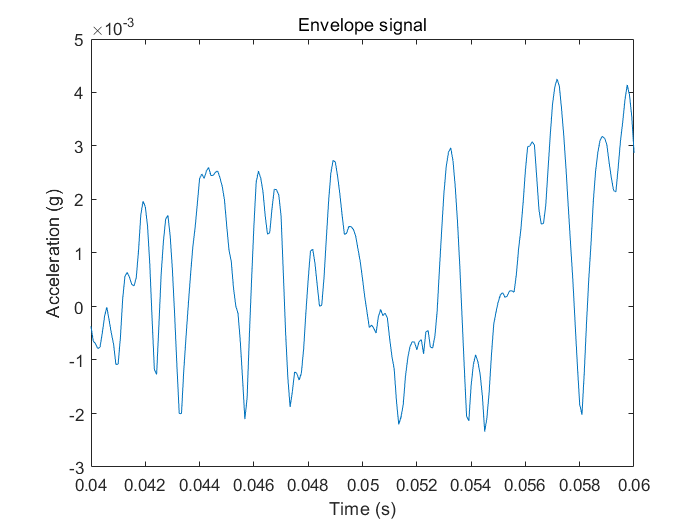


figure(5)
[pEnvNormal, fEnvNormal, xEnvNormal, tEnvNormal] = envspectrum(X098_DE_time, fs);

plot(tEnvNormal, xEnvNormal)
xlim([0.04 0.06])
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Envelope signal')

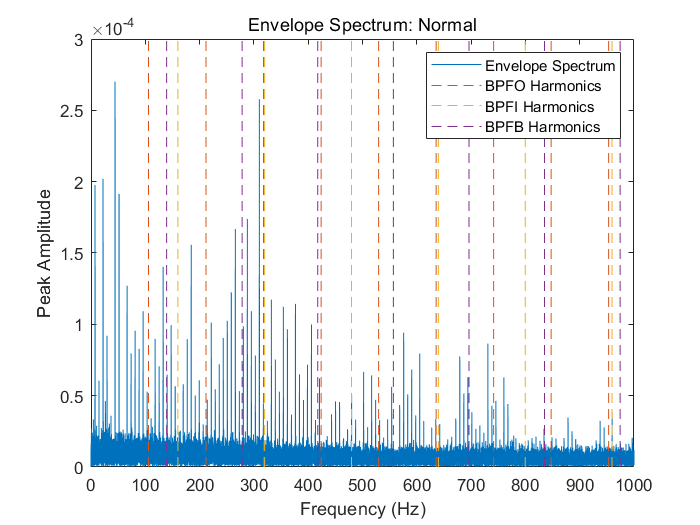


figure(6)
plot(fEnvNormal, pEnvNormal)
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)');
ylabel('Peak Amplitude');
title('Envelope Spectrum: Normal');
legend('Envelope Spectrum', 'BPFO Harmonics','BPFI Harmonics','BPFB Harmonics');
xlim([0 1000])

Even at the enveloped signal, there was no clear pattern which visible at BPFO&BPFI&BPFB and its harmonics.

**• Plot  STFT of given signal**

To see the distribution of frequencies over time, STFT was used.

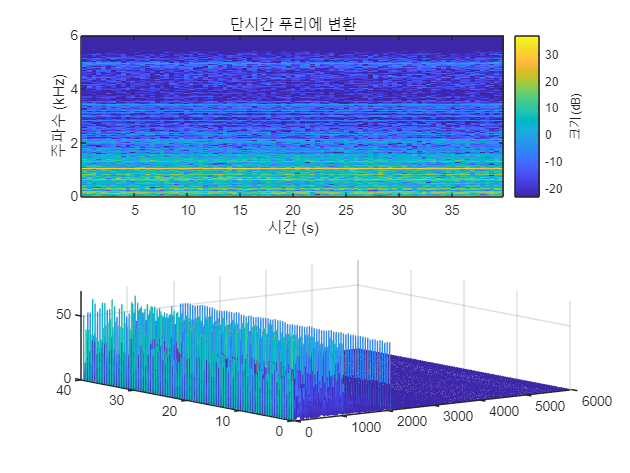

figure(7)

subplot(2, 1, 1);
stft(X098_DE_time,fs,'Window',hamming(6000,'periodic'),'OverlapLength',500,'FrequencyRange','onesided');

subplot(2, 1, 2); 
[S,F,T] = stft(X098_DE_time,fs,'Window',hamming(6000,'periodic'),'OverlapLength',500,'FrequencyRange','onesided');
waterfall(F,T,abs(S)')

**• Plot  Kurtogram**

To find center of frequency & obtimum window size

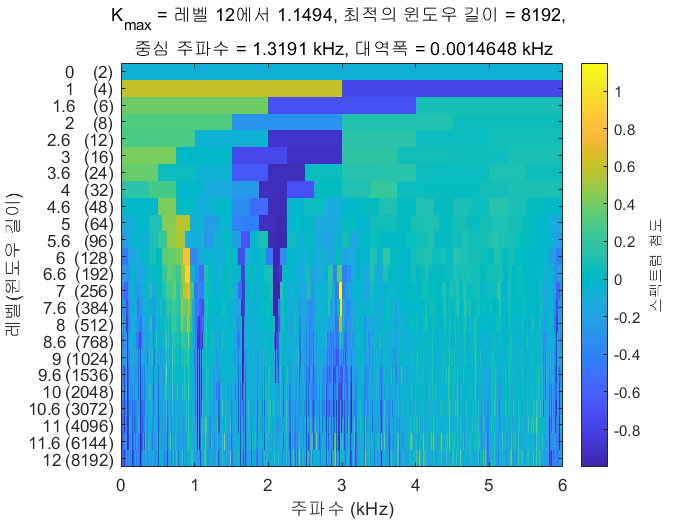

figure(8)

normal_level = 12;
kurtogram(X098_DE_time, fs, normal_level);

**• Plot  Spectral Kurtosis**

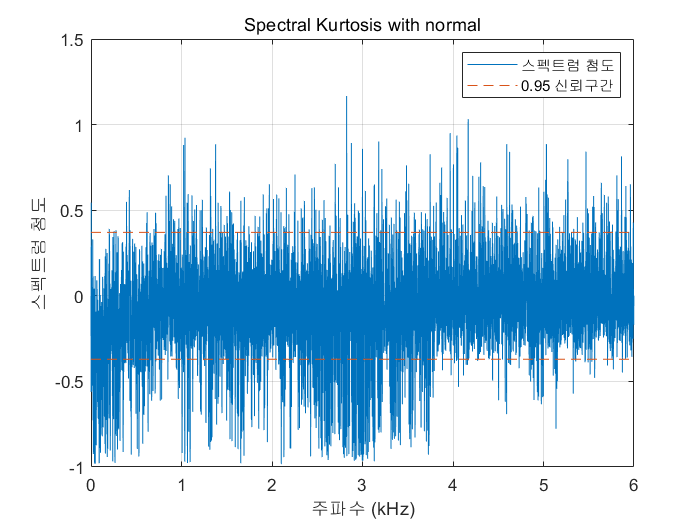

figure(9)
[kgram,f,wc_normal,fc_normal,wc_normal,bw_normal] = kurtogram(X098_DE_time);
pkurtosis(X098_DE_time, fs, wc_normal)
title('Spectral Kurtosis with normal')

Throughout the frequency domain, it can be seen that it does not deviate significantly from the 0.95 confidence interval.

**• Apply bandpass filtering**

To visualize the frequency band on a spectrogram, compute the spectrogram and place the spectral kurtosis on the side. 

To interpret the spectral kurtosis in another way, **high spectral kurtosis values indicates high variance of power at the corresponding frequency**, which makes spectral kurtosis a useful tool to locate nonstationary components of the signal.

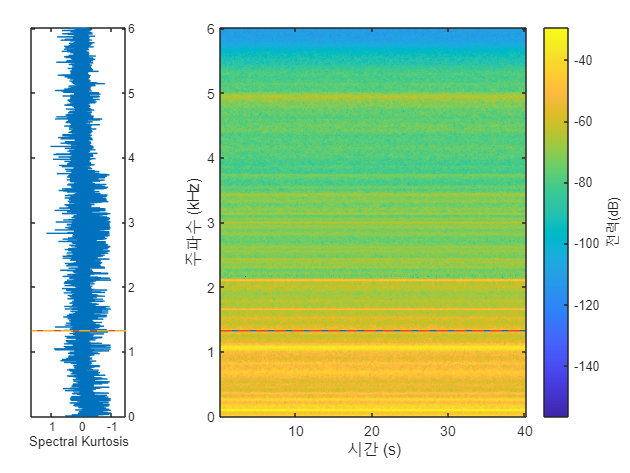

figure(10)
helperSpectrogramAndSpectralKurtosis(X098_DE_time, fs, normal_level)

By bandpass filtering the signal with the suggested center frequency and bandwidth, the kurtosis can be enhanced and the modulated amplitude of the outer race fault can be retrieved.

% Design bandpass filter
bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', fc_normal-bw_normal/2, ...
    'CutoffFrequency2', fc_normal+bw_normal/2, 'SampleRate', fs);

% Apply bandpass filter
xNormalBpf = filter(bpf, X098_DE_time);

% Calculate Kurtosis
kurtNormal = kurtosis(X098_DE_time);
kurtNormalBpf = kurtosis(xNormalBpf);

% Apply bandpass filtered envelope spectrum
[pEnvNormalBpf, fEnvNormalBpf, xEnvNormalBpf, tEnvBpfNormal] = envspectrum(X098_DE_time, fs, ...
    'FilterOrder', 200, 'Band', [fc_normal-bw_normal/2 fc_normal+bw_normal/2]);

Plot band-pass applied envelop spectrum and kurtosis

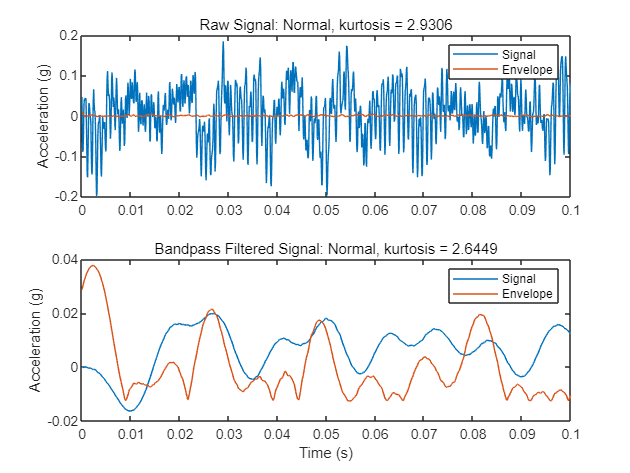

figure(11)
subplot(2, 1, 1)
plot(t_normal_DE, X098_DE_time, tEnvNormal, xEnvNormal)
ylabel('Acceleration (g)')
title(['Raw Signal: Normal, kurtosis = ', num2str(kurtNormal)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(t_normal_DE, xNormalBpf, tEnvBpfNormal, xEnvNormalBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: Normal, kurtosis = ', num2str(kurtNormalBpf)])
legend('Signal', 'Envelope')

It can be seen that the kurtosis value is decreased after bandpass filtering.

 Now visualize the envelope signal in frequency domain.

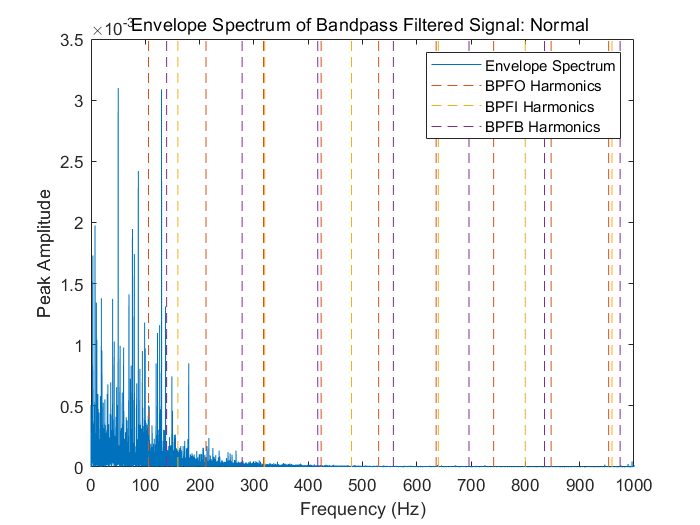

figure(12)

plot(fEnvNormalBpf, pEnvNormalBpf);
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlim([0 1000])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum of Bandpass Filtered Signal: Normal ')
legend('Envelope Spectrum', 'BPFO Harmonics','BPFI Harmonics','BPFB Harmonics');

It is shown that by bandpass filtering the raw signal with the frequency band suggested by kurtogram and spectral kurtosis, the envelope spectrum analysis is able to reveal the fault signature at BPFO and its harmonics.

## **2. Class : Outer**

**• Time-Domain Signal**

Plot the raw outer race fault data in the time domain.

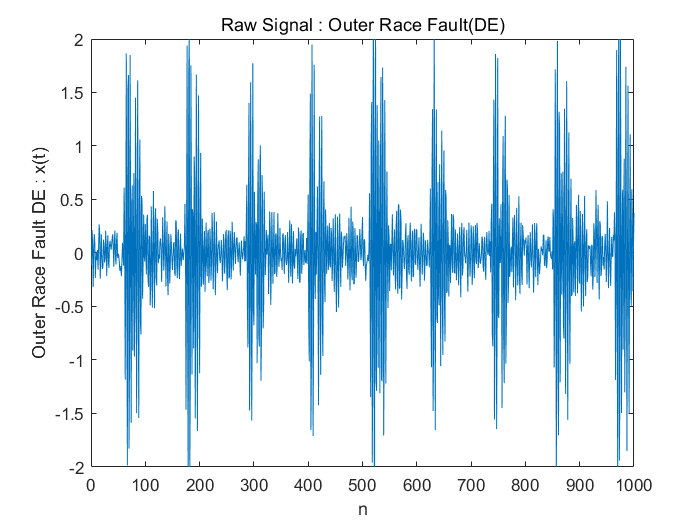

figure(13)

plot(X131_DE_time(1:1000));
ylim([-2, 2])
title('Raw Signal : Outer Race Fault(DE)'); 
xlabel('n'); ylabel('Outer Race Fault DE : x(t)');

Since pulses were observed periodically, I zoomed in.

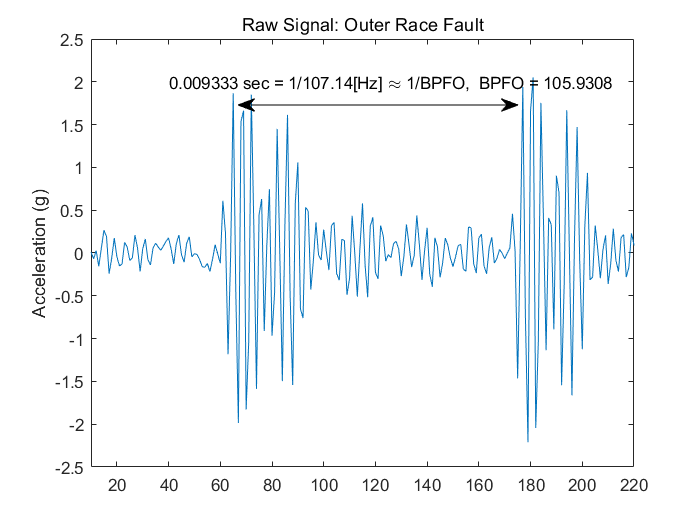

figure(14)
plot(X131_DE_time(1:1000));
xlim([10 220])
title('Raw Signal: Outer Race Fault')
ylabel('Acceleration (g)')
annotation('doublearrow', [0.34 0.74], [0.8 0.8])
text(40, 2, ['0.009333 sec = 1/107.14[Hz] \approx 1/BPFO,  BPFO = ' num2str(BPFO_freq)])

It was confirmed that a frequency similar to that of BPFO was detected.

**• Time Statistical Features **

outer_time_DE  = timeFeatures(X131_DE_time)

outer_time_DE = 1×10 table
      rms        sra       kv         sv        ppv        cf        if        mf        sf        kf  
    _______    _______    _____    ________    ______    ______    ______    ______    ______    ______

    0.59195    0.26626    7.595    0.033401    6.1242    5.2577    8.4927    11.689    1.6153    61.858


**• Frequency Statistical Features **

outer_freq_DE  = freqFeatures(X131_DE_freq)

outer_freq_DE = 1×3 table
        fc          rmsf          rvf   
    __________    _________    _________

    0.00083659    0.0033835    0.0032785


**• Plot FFT/PSD**

: The following graph is output to check what the main frequencies constituting the signal are, and to check what magnitude each frequency has.

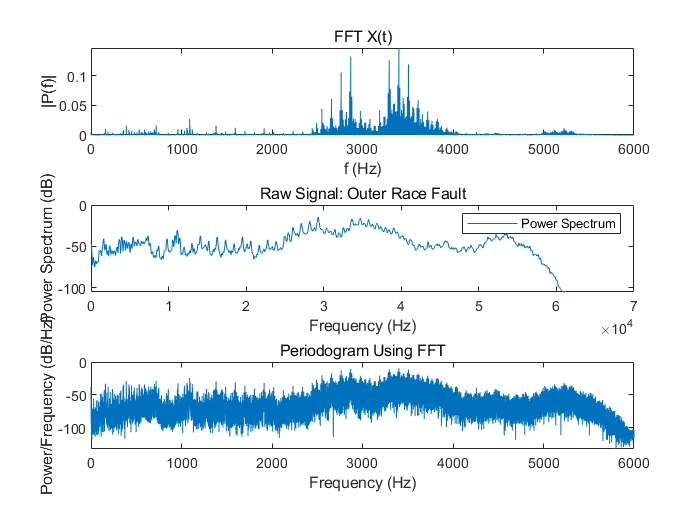

figure(15)
subplot(3, 1, 1)
plot(Freq_outer_DE, X131_DE_freq) 
title('FFT X(t)')
xlabel('f (Hz)')
ylabel('|P(f)|')

subplot(3, 1, 2)
[pOuter, fpOuter] = pspectrum(X131_DE_time, N_outer_DE);
plot(fpOuter, 10*log10(pOuter))
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Raw Signal: Outer Race Fault')
legend('Power Spectrum')

subplot(3, 1, 3)
outer_psdx = getPSD(X131_DE_time, N_outer_DE, fs);
plot(Freq_outer_DE, 10*log10(outer_psdx));
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')

Now zoom in the power spectrum of the raw signal in low frequency range to take a closer look at the frequency response at BPFO & BPFI & BPFB and its first several harmonics.

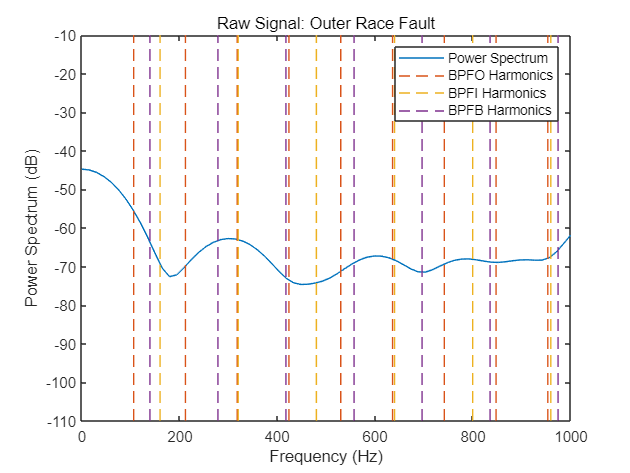

figure(16)

plot(fpOuter, 10*log10(pOuter))
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Raw Signal: Outer Race Fault')
legend('Power Spectrum', 'BPFO Harmonics', 'BPFI Harmonics', 'BPFB Harmonics')
xlim([0 1000])

No clear pattern is visible at BPFO & BPFI & BPFB and its harmonics. Frequency analysis on the raw signal does not provide useful diagnosis information.

--> Use Envelop Extraction

**• Envelop Extraction**

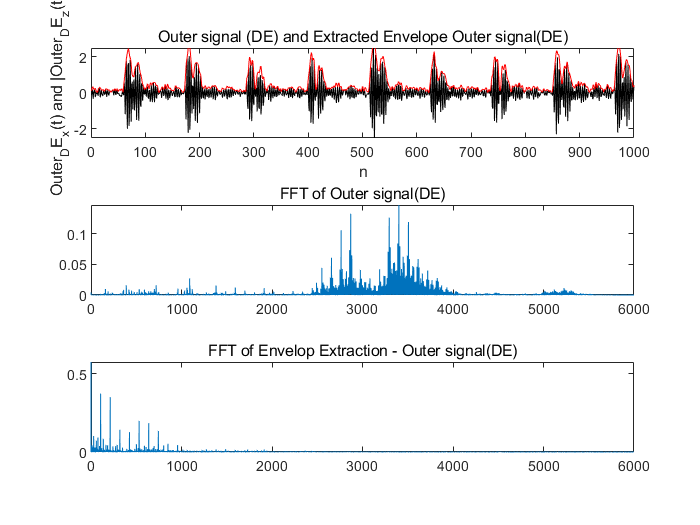

outer_envelop_extraction_DE  = analyticSignal(X131_DE_time);

figure(17)

subplot(3, 1, 1); 
plot(X131_DE_time(1:1000), 'k'); hold on; 
plot(abs(outer_envelop_extraction_DE(1:1000)),'r');
ylim([-2.5, 2.5])
title('Outer signal (DE) and Extracted Envelope Outer signal(DE)'); 
xlabel('n'); ylabel('Outer_DE_x(t) and |Outer_DE_z(t)|');

subplot(3, 1, 2);
plot(Freq_outer_DE, X131_DE_freq); % X131_DE_freq = getFFT(X131_DE_time, N_outer_DE)
title('FFT of Outer signal(DE)');

subplot(3, 1, 3); 
outer_envelop_fft_DE = getFFT(abs(outer_envelop_extraction_DE), N_outer_DE);
plot(Freq_outer_DE, outer_envelop_fft_DE);
title('FFT of Envelop Extraction - Outer signal(DE)');

Now zoom in the Envelope spectrum in low frequency range to take a closer look at the frequency response at BPFO & BPFI & BPFB and its first several harmonics.

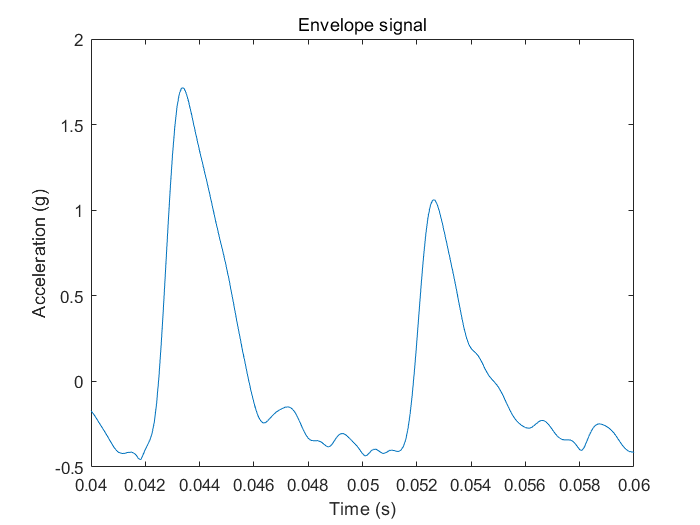


figure(18)
[pEnvOuter, fEnvOuter, xEnvOuter, tEnvOuter] = envspectrum(X131_DE_time, fs);

plot(tEnvOuter, xEnvOuter)
xlim([0.04 0.06])
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Envelope signal')

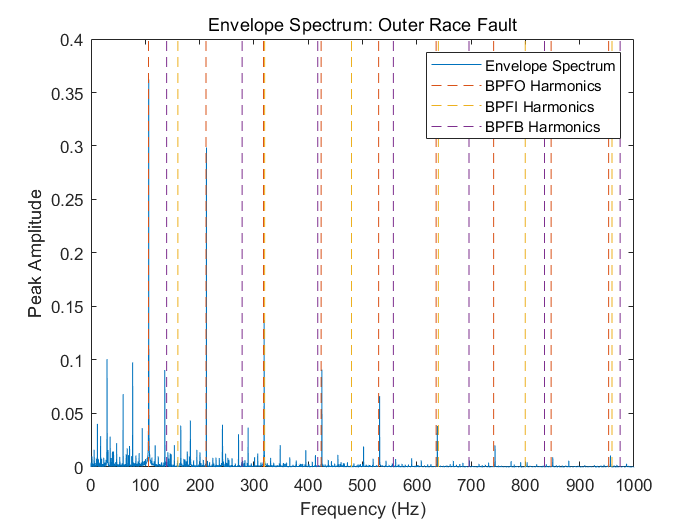


figure(16)
plot(fEnvOuter, pEnvOuter)
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)');
ylabel('Peak Amplitude');
title('Envelope Spectrum: Outer Race Fault');
legend('Envelope Spectrum', 'BPFO Harmonics','BPFI Harmonics','BPFB Harmonics');
xlim([0 1000])

It was confirmed that the detected frequency was almost identical to the BPFO.

**• Plot  STFT of given signal**

To see the distribution of frequencies over time, STFT was used.

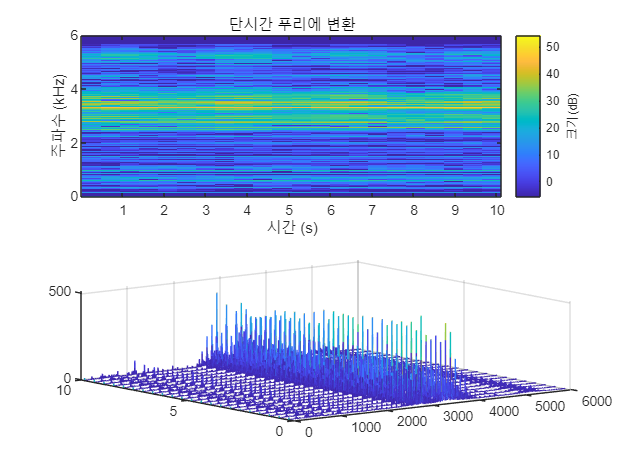

figure(19)

subplot(2, 1, 1);
stft(X131_DE_time,fs,'Window',hamming(6000,'periodic'),'OverlapLength',500,'FrequencyRange','onesided');

subplot(2, 1, 2); 
[S,F,T] = stft(X131_DE_time,fs,'Window',hamming(6000,'periodic'),'OverlapLength',500,'FrequencyRange','onesided');
waterfall(F,T,abs(S)')

**• Plot  Kurtogram**

To find center of frequency & obtimum window size

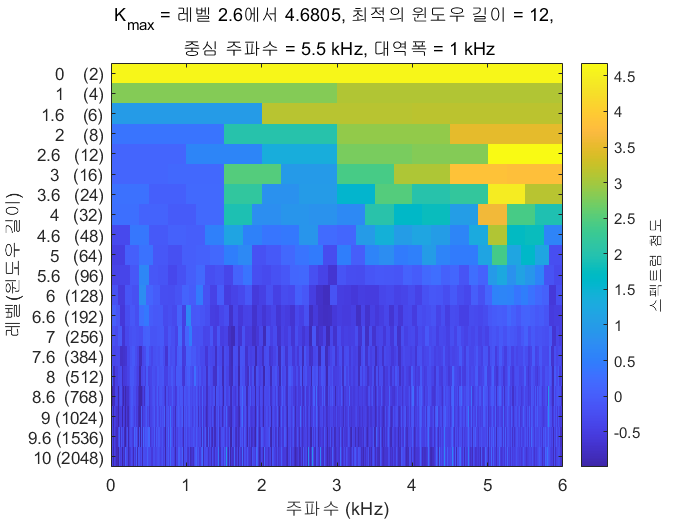

figure(20)

outer_level = 10;
kurtogram(X131_DE_time, fs, outer_level);

**• Plot  Spectral Kurtosis**

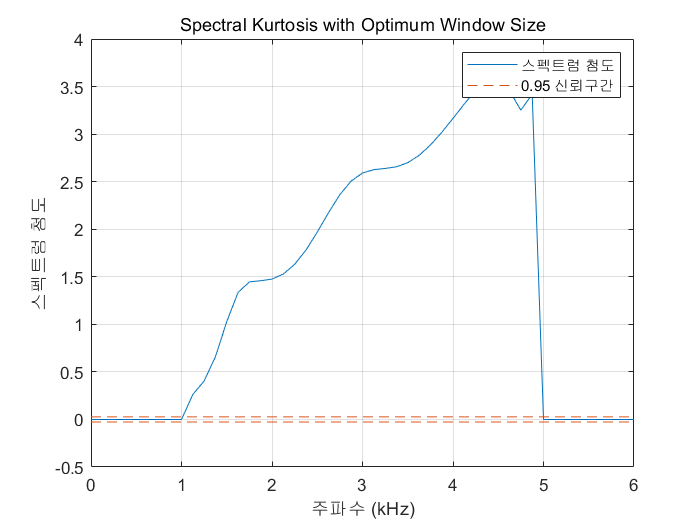

figure(21)

[~,~,~,fc_outer,wc_outer,bw_outer] = kurtogram(X131_DE_time, fs, outer_level);
pkurtosis(X131_DE_time, fs, wc_outer)
title('Spectral Kurtosis with Optimum Window Size')

Throughout the frequency domain, it was confirmed that it was significantly out of the 0.95 confidence interval.

**• Apply bandpass filtering**

To visualize the frequency band on a spectrogram, compute the spectrogram and place the spectral kurtosis on the side. 

To interpret the spectral kurtosis in another way, **high spectral kurtosis values indicates high variance of power at the corresponding frequency**, which makes spectral kurtosis a useful tool to locate nonstationary components of the signal.

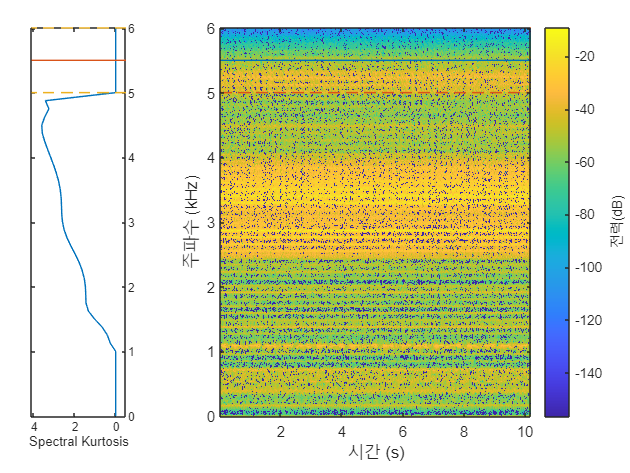

figure(22)
helperSpectrogramAndSpectralKurtosis(X131_DE_time, fs, outer_level)

By bandpass filtering the signal with the suggested center frequency and bandwidth, the kurtosis can be enhanced and the modulated amplitude of the outer race fault can be retrieved.

% Design bandpass filter
bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', fc_outer-bw_outer/2 + 1, ...
    'CutoffFrequency2', fc_outer+bw_outer/2 - 1, 'SampleRate', fs);

% Apply bandpass filter
xOuterBpf = filter(bpf, X131_DE_time);

% Calculate Kurtosis
kurtOuter = kurtosis(X131_DE_time);
kurtOuterBpf = kurtosis(xOuterBpf);

% Apply bandpass filtered envelope spectrum
[pEnvOuterBpf, fEnvOuterBpf, xEnvOuterBpf, tEnvBpfOuter] = envspectrum(X131_DE_time, fs, ...
    'FilterOrder', 200, 'Band', [(fc_outer-bw_outer/2)/fs (fc_outer+bw_outer/2)/fs]);

Plot band-pass applied envelop spectrum and kurtosis

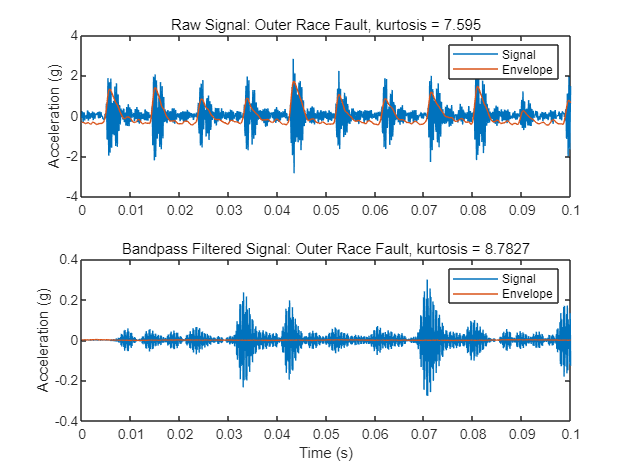

figure(23)
subplot(2, 1, 1)
plot(t_outer_DE(1 : end - 1), X131_DE_time, tEnvOuter, xEnvOuter)
ylabel('Acceleration (g)')
title(['Raw Signal: Outer Race Fault, kurtosis = ', num2str(kurtOuter)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(t_outer_DE(1 : end - 1), xOuterBpf, tEnvBpfOuter, xEnvOuterBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: Outer Race Fault, kurtosis = ', num2str(kurtOuterBpf)])
legend('Signal', 'Envelope')

It can be seen that the kurtosis value is decreased after bandpass filtering.

 Now visualize the envelope signal in frequency domain.

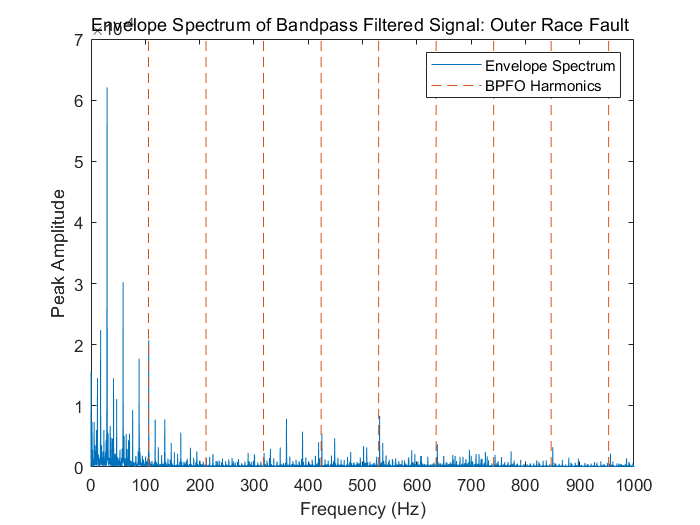

figure(24)

plot(fEnvOuterBpf, pEnvOuterBpf);
ncomb = 10;
helperPlotCombs(ncomb, BPFO_freq)
xlim([0 1000])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum of Bandpass Filtered Signal: Outer Race Fault ')
legend('Envelope Spectrum', 'BPFO Harmonics')

It is shown that by bandpass filtering the raw signal with the frequency band suggested by kurtogram and spectral kurtosis, the envelope spectrum analysis is able to reveal the fault signature at BPFO and its harmonics.

## **3. Class : Inner**

**• Time-Domain Signal**

Plot the raw normal data in the time domain.

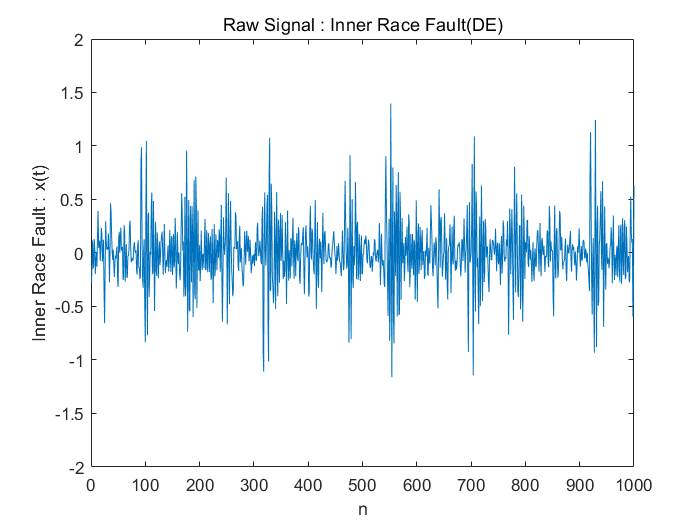

figure(25)

plot(X106_DE_time(1:1000));
ylim([-2, 2])
title('Raw Signal : Inner Race Fault(DE)'); 
xlabel('n'); ylabel('Inner Race Fault : x(t)');

**• Time Statistical Features **

inner_time_DE  = timeFeatures(X106_DE_time)

inner_time_DE = 1×10 table
      rms        sra        kv        sv        ppv        cf        if        mf        sf       kf  
    _______    _______    ______    _______    ______    ______    ______    ______    ______    _____

    0.29289    0.16484    5.5423    0.13043    2.9838    5.3973    7.6131    9.5902    1.4105    753.1


**• Frequency Statistical Features **

inner_freq_DE  = freqFeatures(X106_DE_freq)

inner_freq_DE = 1×3 table
        fc          rmsf         rvf   
    __________    ________    _________

    0.00051092    0.001677    0.0015973


**• Plot FFT/PSD**

: The following graph is output to check what the main frequencies constituting the signal are, and to check what magnitude each frequency has.

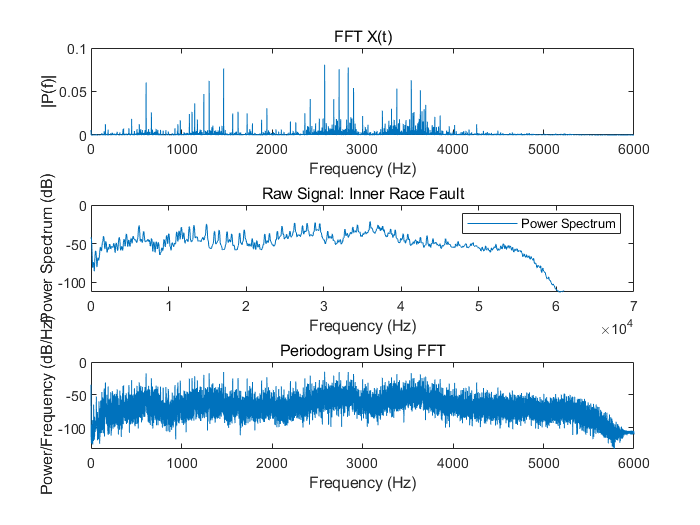

figure(26)
subplot(3, 1, 1)
plot(Freq_inner_DE, X106_DE_freq) 
title('FFT X(t)')
xlabel('Frequency (Hz)')
ylabel('|P(f)|')

subplot(3, 1, 2)
[pInner, fpInner] = pspectrum(X106_DE_time, N_inner_DE);
plot(fpInner, 10*log10(pInner))
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Raw Signal: Inner Race Fault')
legend('Power Spectrum')

subplot(3, 1, 3)
inner_psdx = getPSD(X106_DE_time, N_inner_DE, fs);
plot(Freq_inner_DE, 10*log10(inner_psdx));
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')

Now zoom in the power spectrum of the raw signal in low frequency range to take a closer look at the frequency response at BPFO & BPFI & BPFB and its first several harmonics.

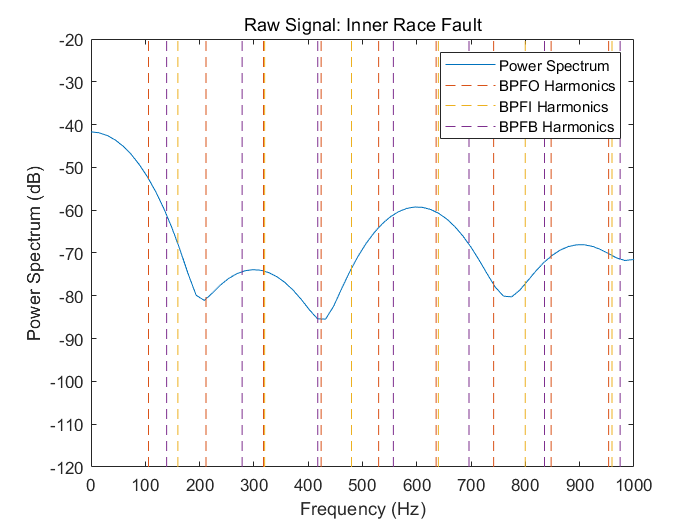

figure(27)

plot(fpInner, 10*log10(pInner))
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Raw Signal: Inner Race Fault')
legend('Power Spectrum', 'BPFO Harmonics', 'BPFI Harmonics', 'BPFB Harmonics')
xlim([0 1000])

No clear pattern is visible at BPFI and its harmonics. Frequency analysis on the raw signal does not provide useful diagnosis information.

--> Use Envelop Extraction

**• Envelop Extraction**

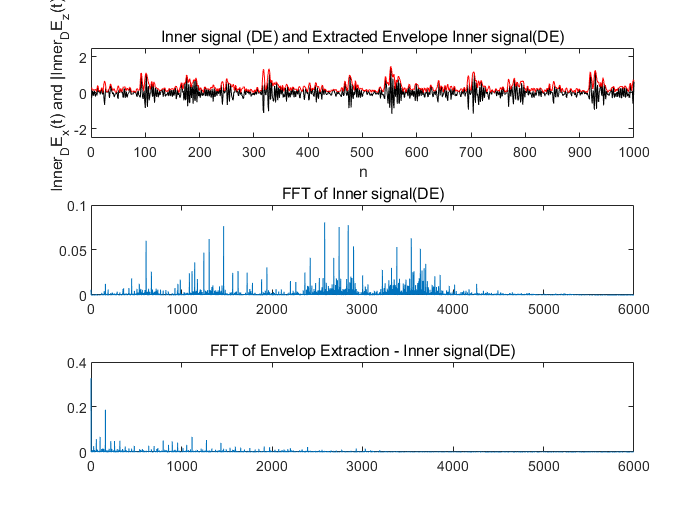

inner_envelop_extraction_DE  = analyticSignal(X106_DE_time(1 : end-1));

figure(28)

subplot(3, 1, 1); 
plot(X106_DE_time(1:1000), 'k'); hold on; 
plot(abs(inner_envelop_extraction_DE(1:1000)),'r');
ylim([-2.5, 2.5])
title('Inner signal (DE) and Extracted Envelope Inner signal(DE)'); 
xlabel('n'); ylabel('Inner_DE_x(t) and |Inner_DE_z(t)|');

subplot(3, 1, 2);
plot(Freq_inner_DE, X106_DE_freq); % X106_DE_freq = getFFT(X106_DE_time, N_inner_DE)
title('FFT of Inner signal(DE)');

subplot(3, 1, 3); 
inner_envelop_fft_DE = getFFT(abs(inner_envelop_extraction_DE), N_inner_DE);
plot(Freq_inner_DE, inner_envelop_fft_DE);
title('FFT of Envelop Extraction - Inner signal(DE)');

Now zoom in the Envelope spectrum in low frequency range to take a closer look at the frequency response at BPFO & BPFI & BPFB and its first several harmonics.

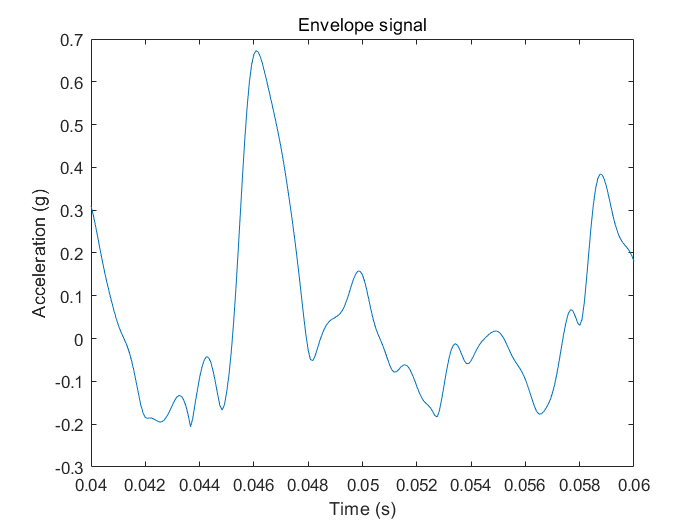


figure(29)
[pEnvInner, fEnvInner, xEnvInner, tEnvInner] = envspectrum(X106_DE_time, fs);

plot(tEnvInner, xEnvInner)
xlim([0.04 0.06])
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Envelope signal')

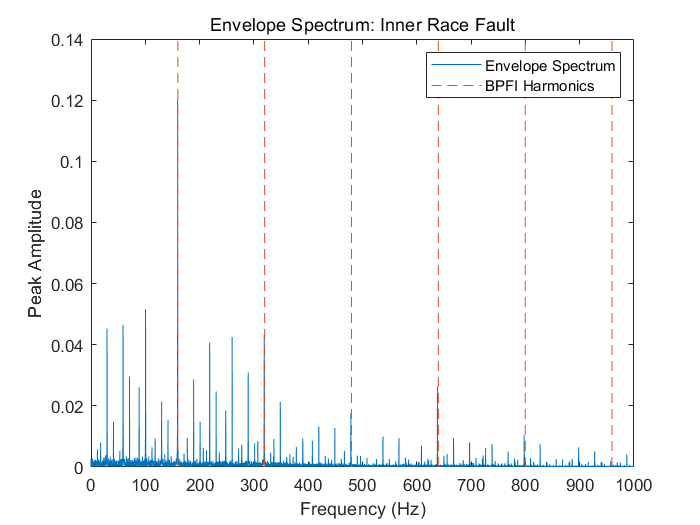


figure(30)

plot(fEnvInner, pEnvInner)
ncomb = 10;
helperPlotCombs(ncomb, BPFI_freq)
xlabel('Frequency (Hz)');
ylabel('Peak Amplitude');
title('Envelope Spectrum: Inner Race Fault');
legend('Envelope Spectrum', 'BPFI Harmonics');
xlim([0 1000])

It was confirmed that the detected frequency was almost identical to the BPFI.

**• Plot  STFT of given signal**

To see the distribution of frequencies over time, STFT was used.

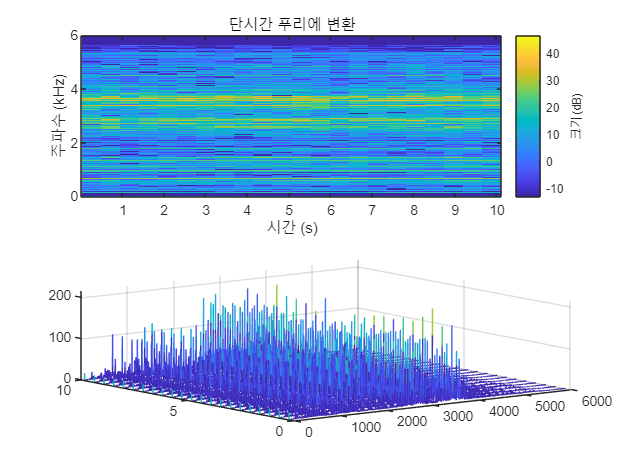

figure(31)

subplot(2, 1, 1);
stft(X106_DE_time,fs,'Window',hamming(6000,'periodic'),'OverlapLength',500,'FrequencyRange','onesided');

subplot(2, 1, 2); 
[S,F,T] = stft(X106_DE_time,fs,'Window',hamming(6000,'periodic'),'OverlapLength',500,'FrequencyRange','onesided');
waterfall(F,T,abs(S)')

**• Plot  Kurtogram**

To find center of frequency & obtimum window size

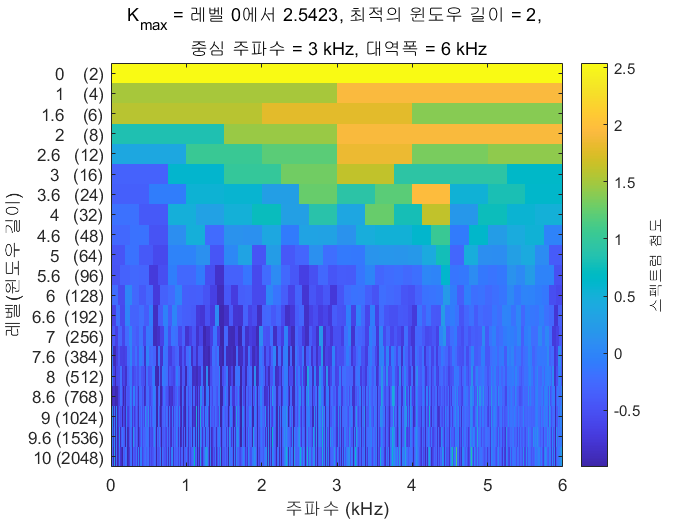

figure(32)

inner_level = 10;
kurtogram(X106_DE_time, fs, inner_level);

**• Plot  Spectral Kurtosis**

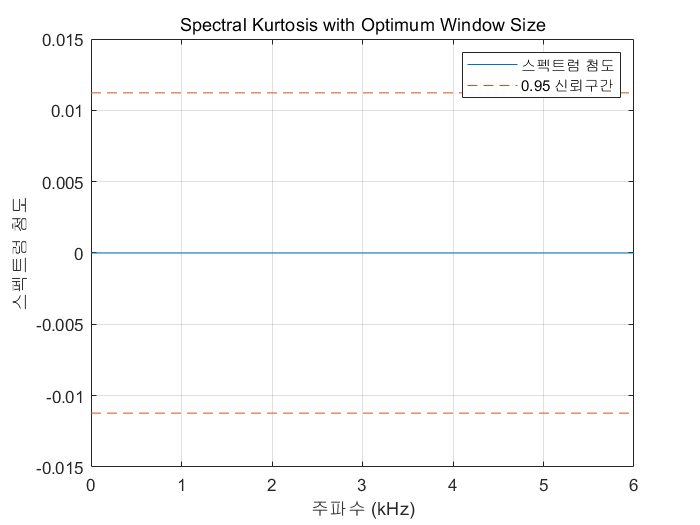

figure(33)

[~,~,~,fc_inner,wc_inner,bw_inner] = kurtogram(X106_DE_time, fs, inner_level);
pkurtosis(X106_DE_time, fs, wc_inner)
title('Spectral Kurtosis with Optimum Window Size')

**• Apply bandpass filtering**

To visualize the frequency band on a spectrogram, compute the spectrogram and place the spectral kurtosis on the side. 

To interpret the spectral kurtosis in another way, **high spectral kurtosis values indicates high variance of power at the corresponding frequency**, which makes spectral kurtosis a useful tool to locate nonstationary components of the signal.

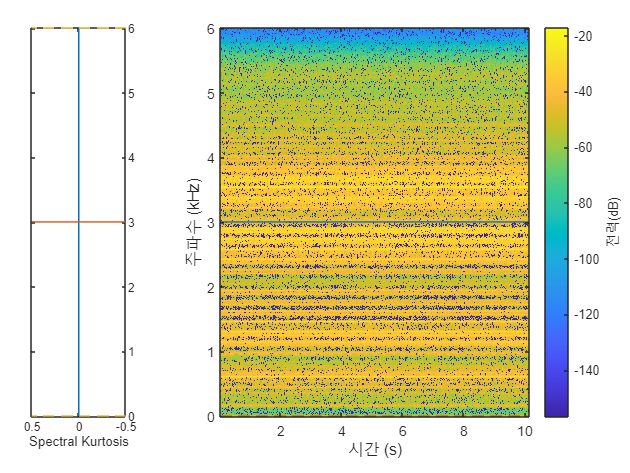

figure(34)
helperSpectrogramAndSpectralKurtosis(X106_DE_time, fs, inner_level)

By bandpass filtering the signal with the suggested center frequency and bandwidth, the kurtosis can be enhanced and the modulated amplitude of the outer race fault can be retrieved.

% Design bandpass filter
bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', (fc_inner - bw_inner/2 + 1), ...
    'CutoffFrequency2', (fc_inner + bw_inner/2 - 1), 'SampleRate', fs);

% Apply bandpass filter
xInnerBpf = filter(bpf, X106_DE_time);

% Calculate Kurtosis
kurtInner = kurtosis(X106_DE_time);
kurtInnerBpf = kurtosis(xInnerBpf);

% Apply bandpass filtered envelope spectrum
[pEnvInnerBpf, fEnvInnerBpf, xEnvInnerBpf, tEnvBpfInner] = envspectrum(X106_DE_time, fs, ...
    'FilterOrder', 200, 'Band', [(fc_inner-bw_inner/2)/fs (fc_inner+bw_inner/2)/fs]);

Plot band-pass applied envelop spectrum and kurtosis

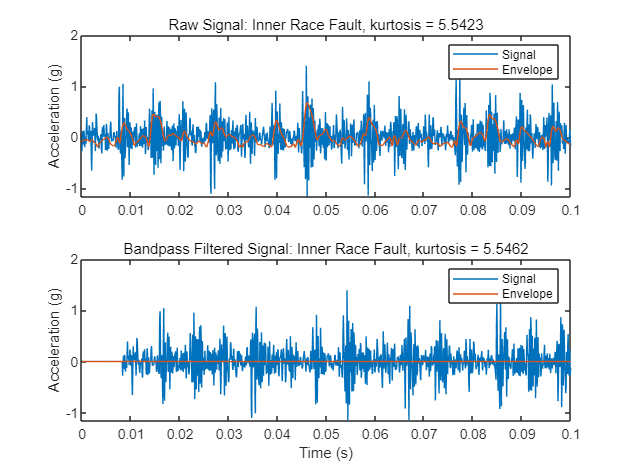

figure(35)

subplot(2, 1, 1)
plot(t_inner_DE, X106_DE_time, tEnvInner, xEnvInner)
ylabel('Acceleration (g)')
title(['Raw Signal: Inner Race Fault, kurtosis = ', num2str(kurtInner)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(t_inner_DE, xInnerBpf, tEnvBpfInner, xEnvInnerBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: Inner Race Fault, kurtosis = ', num2str(kurtInnerBpf)])
legend('Signal', 'Envelope')

It can be seen that the kurtosis value is slightly increased after bandpass filtering.

Now visualize the envelope signal in frequency domain.

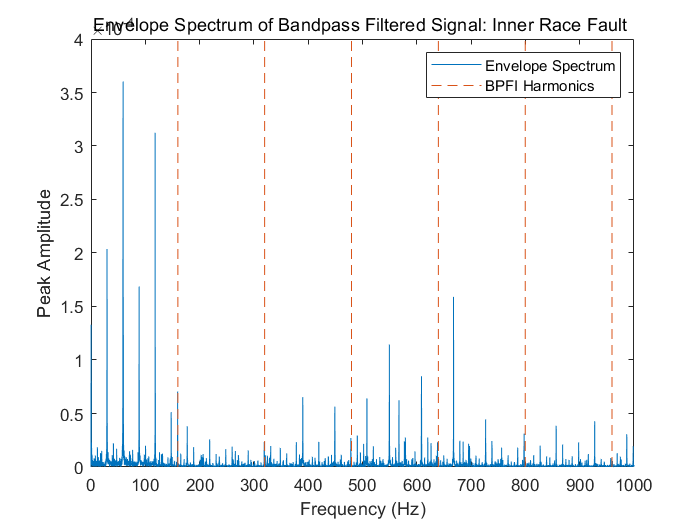

figure(36)
plot(fEnvInnerBpf, pEnvInnerBpf);
ncomb = 10;
helperPlotCombs(ncomb, BPFI_freq)
xlim([0 1000])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum of Bandpass Filtered Signal: Inner Race Fault ')
legend('Envelope Spectrum', 'BPFI Harmonics')

It is shown that by bandpass filtering the raw signal with the frequency band suggested by kurtogram and spectral kurtosis, the envelope spectrum analysis is able to reveal the fault signature at BPFO and its harmonics. However, it can be seen that the peak value has decreased significantly compared to before applying the filter.

## **4. Class : Ball**

**• Time-Domain Signal**

Plot the raw normal data in the time domain.

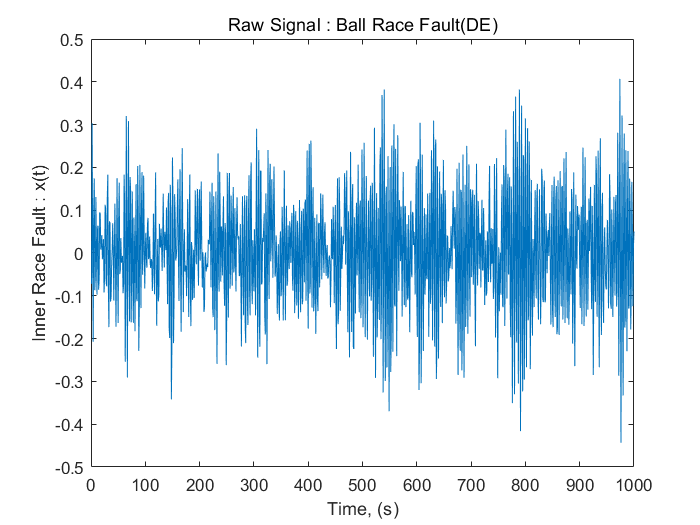

figure(37)

plot(X119_DE_time(1:1000));
ylim([-0.5, 0.5])
title('Raw Signal : Ball Race Fault(DE)'); 
xlabel('Time, (s)'); ylabel('Inner Race Fault : x(t)');

**• Time Statistical Features **

ball_time_DE   = timeFeatures(X119_DE_time)

ball_time_DE = 1×10 table
      rms        sra         kv         sv         ppv        cf        if        mf        sf        kf  
    _______    ________    ______    _________    ______    ______    ______    ______    ______    ______

    0.13907    0.094363    2.9638    0.0074533    1.2993    4.7433    5.9312    6.9905    1.2504    7923.7


**• Frequency Statistical Features **

ball_freq_DE   = freqFeatures(X119_DE_freq)

ball_freq_DE = 1×3 table
        fc           rmsf          rvf    
    __________    __________    __________

    0.00026417    0.00079807    0.00075309


**• Plot FFT/PSD**

: The following graph is output to check what the main frequencies constituting the signal are, and to check what magnitude each frequency has.

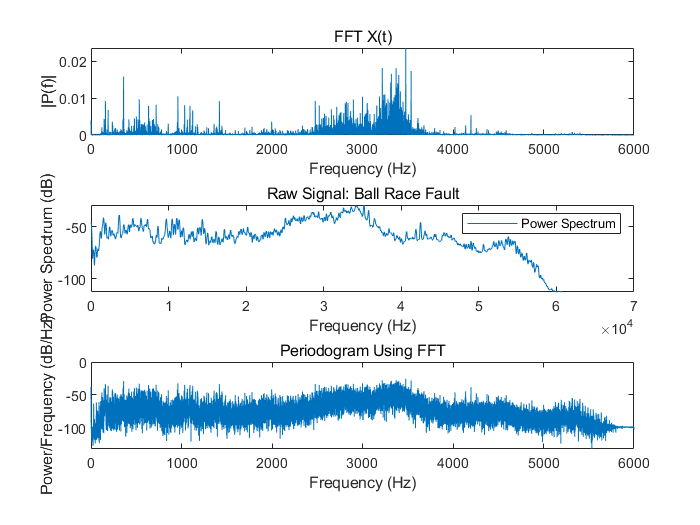

figure(38)
subplot(3, 1, 1)
plot(Freq_ball_DE, X119_DE_freq) 
title('FFT X(t)')
xlabel('Frequency (Hz)')
ylabel('|P(f)|')

subplot(3, 1, 2)
[pBall, fpBall] = pspectrum(X119_DE_time, N_ball_DE);
plot(fpBall, 10*log10(pBall))
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Raw Signal: Ball Race Fault')
legend('Power Spectrum')

subplot(3, 1, 3)
ball_psdx = getPSD(X119_DE_time, N_ball_DE, fs);
plot(Freq_ball_DE, 10*log10(ball_psdx));
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')

Now zoom in the power spectrum of the raw signal in low frequency range to take a closer look at the frequency response at BPFO & BPFI & BPFB and its first several harmonics.

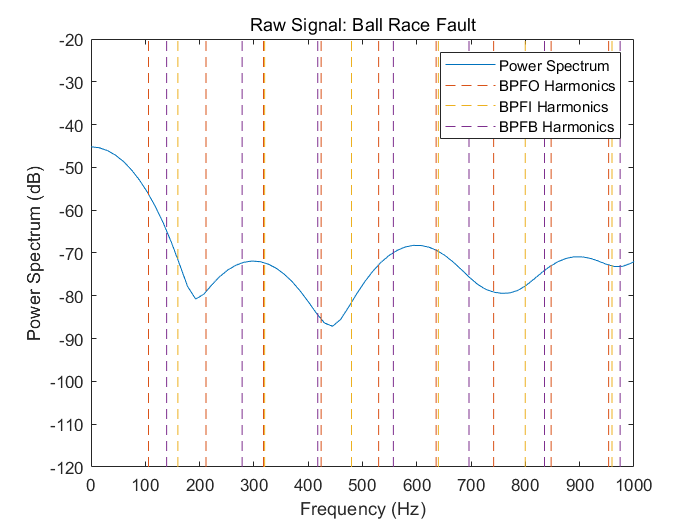

figure(39)

plot(fpBall, 10*log10(pBall))
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Raw Signal: Ball Race Fault')
legend('Power Spectrum', 'BPFO Harmonics', 'BPFI Harmonics', 'BPFB Harmonics')
xlim([0 1000])

No clear pattern is visible at BPFI and its harmonics. Frequency analysis on the raw signal does not provide useful diagnosis information.

--> Use Envelop Extraction

**• Envelop Extraction**

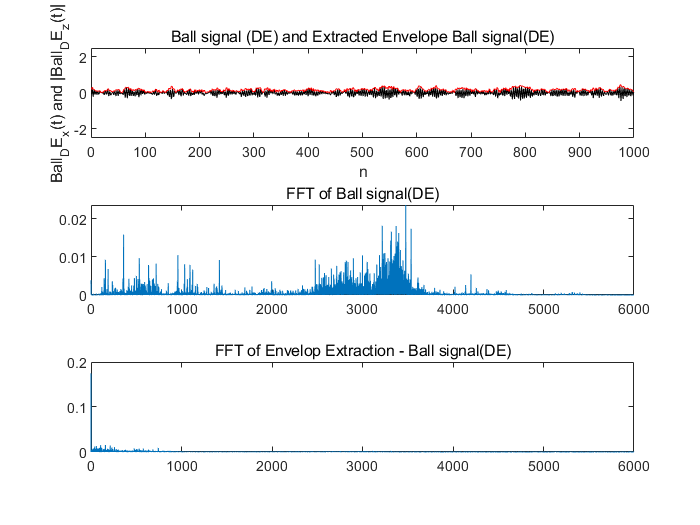

ball_envelop_extraction_DE   = analyticSignal(X119_DE_time);

figure(40)

subplot(3, 1, 1); 
plot(X119_DE_time(1:1000), 'k'); hold on; 
plot(abs(ball_envelop_extraction_DE(1:1000)),'r');
ylim([-2.5, 2.5])
title('Ball signal (DE) and Extracted Envelope Ball signal(DE)'); 
xlabel('n'); ylabel('Ball_DE_x(t) and |Ball_DE_z(t)|');

subplot(3, 1, 2);
plot(Freq_ball_DE, X119_DE_freq); % X119_DE_freq = getFFT(X119_DE_time, N_inner_DE)
title('FFT of Ball signal(DE)');

subplot(3, 1, 3); 
ball_DE_envelop_fft_DE = getFFT(abs(ball_envelop_extraction_DE), N_ball_DE);
plot(Freq_ball_DE, ball_DE_envelop_fft_DE);
title('FFT of Envelop Extraction - Ball signal(DE)');

Now zoom in the Envelope spectrum in low frequency range to take a closer look at the frequency response at BPFO & BPFI & BPFB and its first several harmonics.

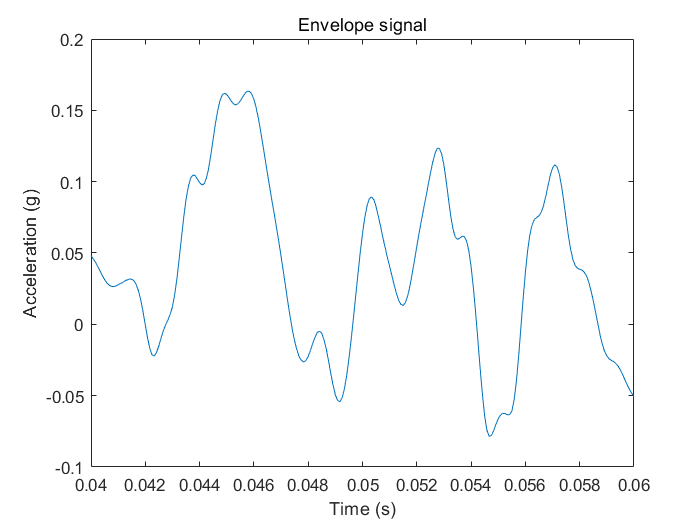


figure(41)
[pEnvBall, fEnvBall, xEnvBall, tEnvBall] = envspectrum(X119_DE_time, fs);

plot(tEnvBall, xEnvBall)
xlim([0.04 0.06])
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Envelope signal')

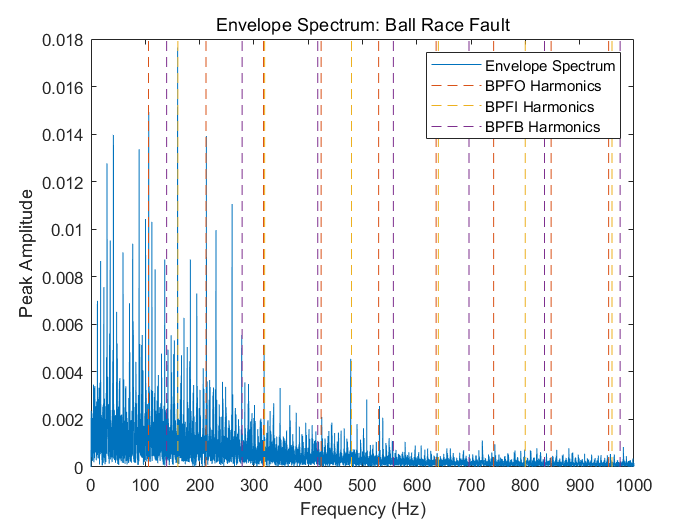


figure(42)
plot(fEnvBall, pEnvBall)
ncomb = 10;
helperPlotCombs(ncomb, [BPFO_freq BPFI_freq BPFB_freq])
xlabel('Frequency (Hz)');
ylabel('Peak Amplitude');
title('Envelope Spectrum: Ball Race Fault');
legend('Envelope Spectrum', 'BPFO Harmonics','BPFI Harmonics','BPFB Harmonics');
xlim([0 1000])

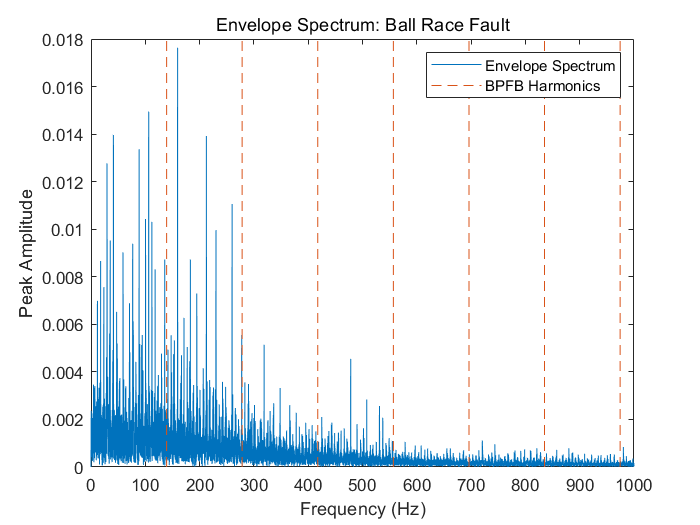


figure(43)
plot(fEnvBall, pEnvBall)
ncomb = 10;
helperPlotCombs(ncomb, BPFB_freq)
xlabel('Frequency (Hz)');
ylabel('Peak Amplitude');
title('Envelope Spectrum: Ball Race Fault');
legend('Envelope Spectrum', 'BPFB Harmonics');
xlim([0 1000])

Although there is a frequency consistent with the BPFB, it is difficult to determine whether the signal itself is frequency or noise.

**• Plot  STFT of given signal**

To see the distribution of frequencies over time, STFT was used.

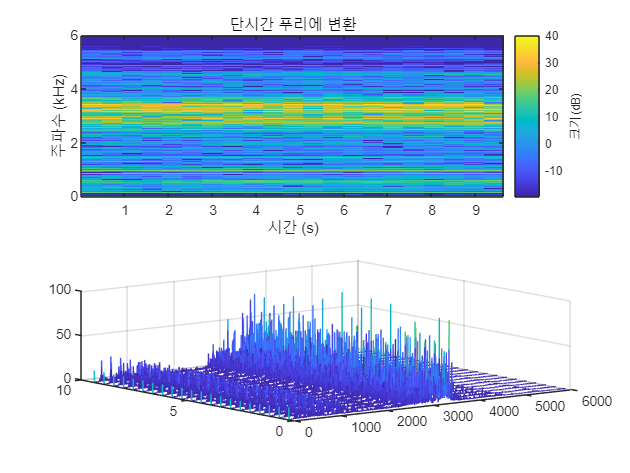

figure(44)

subplot(2, 1, 1);
stft(X119_DE_time,fs,'Window',hamming(6000,'periodic'),'OverlapLength',500,'FrequencyRange','onesided');

subplot(2, 1, 2); 
[S,F,T] = stft(X119_DE_time,fs,'Window',hamming(6000,'periodic'),'OverlapLength',500,'FrequencyRange','onesided');
waterfall(F,T,abs(S)')

**• Plot  Kurtogram**

To find center of frequency & obtimum window size

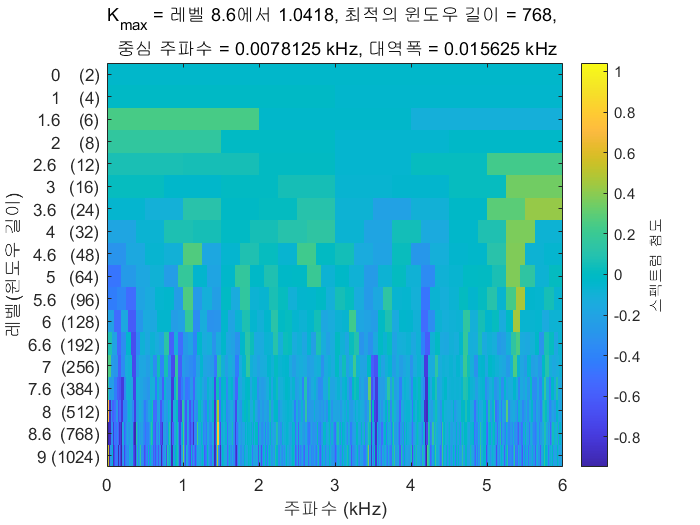

figure(45)

ball_level = 9;
kurtogram(X119_DE_time, fs, ball_level);

**• Plot  Spectral Kurtosis**

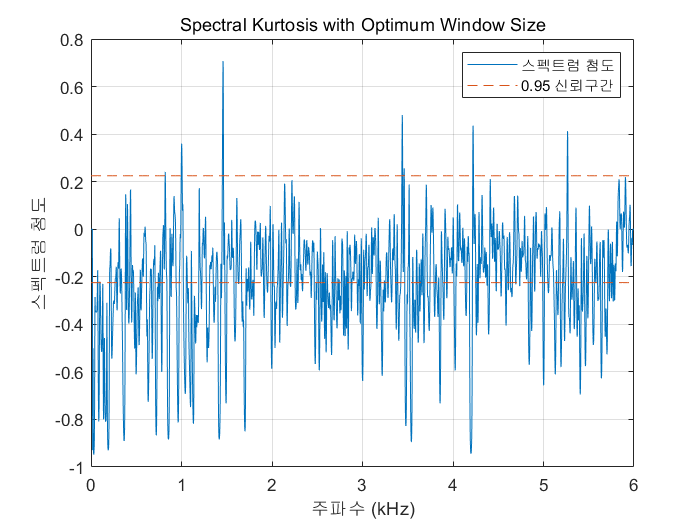

figure(46)

[~,~,~,fc_ball,wc_ball,bw_ball] = kurtogram(X119_DE_time, fs, ball_level);
pkurtosis(X119_DE_time, fs, wc_ball)
title('Spectral Kurtosis with Optimum Window Size')

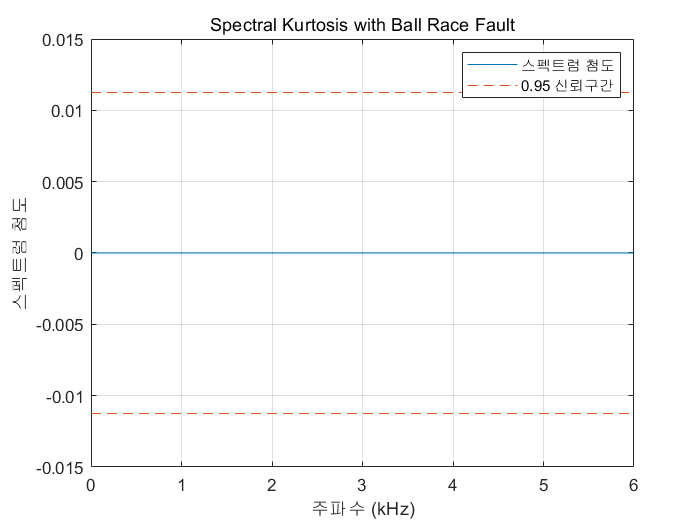


figure(47)
[kgram,f,w,fc_ball,wc_ball,bw_ball] = kurtogram(X106_DE_time);
pkurtosis(X119_DE_time, fs, wc_ball)
title('Spectral Kurtosis with Ball Race Fault')

This signal looks like un-fault signal.

**• Apply bandpass filtering**

To visualize the frequency band on a spectrogram, compute the spectrogram and place the spectral kurtosis on the side. 

To interpret the spectral kurtosis in another way, **high spectral kurtosis values indicates high variance of power at the corresponding frequency**, which makes spectral kurtosis a useful tool to locate nonstationary components of the signal [3].

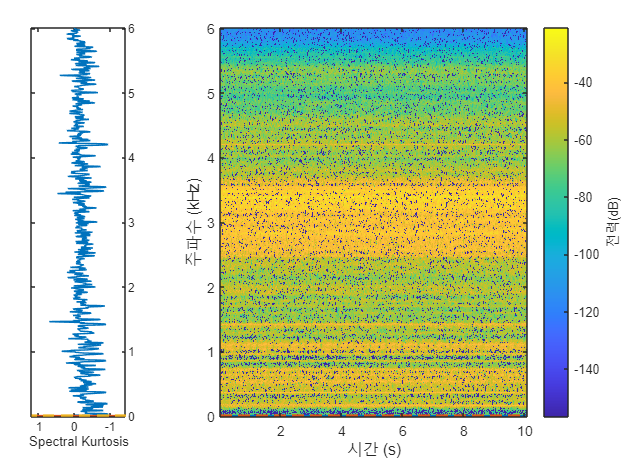

figure(48)
helperSpectrogramAndSpectralKurtosis(X119_DE_time, fs, ball_level)

By bandpass filtering the signal with the suggested center frequency and bandwidth, the kurtosis can be enhanced and the modulated amplitude of the outer race fault can be retrieved.

% Design bandpass filter
bpf = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', (fc_ball - bw_ball/2 + 1), ...
    'CutoffFrequency2', (fc_ball + bw_ball/2 - 1), 'SampleRate', fs);

% Apply bandpass filter
xBallBpf = filter(bpf, X119_DE_time);

% Calculate Kurtosis
kurtBall = kurtosis(X119_DE_time);
kurtBallBpf = kurtosis(xBallBpf);

% Apply bandpass filtered envelope spectrum
[pEnvBallBpf, fEnvBallBpf, xEnvBallBpf, tEnvBpfBall] = envspectrum(X119_DE_time, fs, ...
    'FilterOrder', 200, 'Band', [(fc_ball-bw_ball/2)/fs (fc_ball+bw_ball/2)/fs]);

Plot band-pass applied envelop spectrum and kurtosis

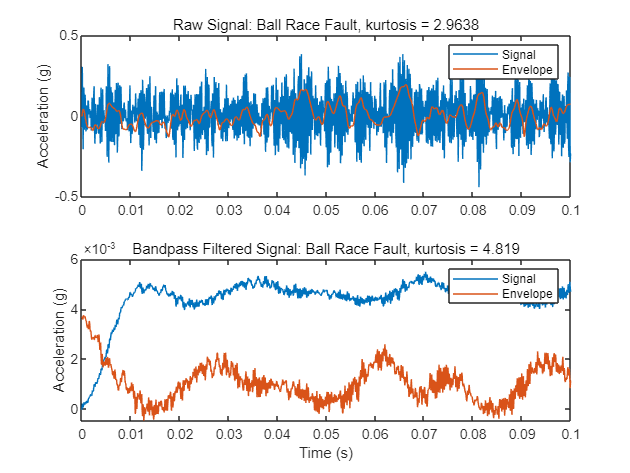

figure(49)
subplot(2, 1, 1)
plot(t_ball_DE, X119_DE_time, tEnvBall, xEnvBall)
ylabel('Acceleration (g)')
title(['Raw Signal: Ball Race Fault, kurtosis = ', num2str(kurtBall)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(t_ball_DE, xBallBpf, tEnvBpfBall, xEnvBallBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: Ball Race Fault, kurtosis = ', num2str(kurtBallBpf)])
legend('Signal', 'Envelope')

It can be seen that the kurtosis value is increased after bandpass filtering.

 Now visualize the envelope signal in frequency domain.

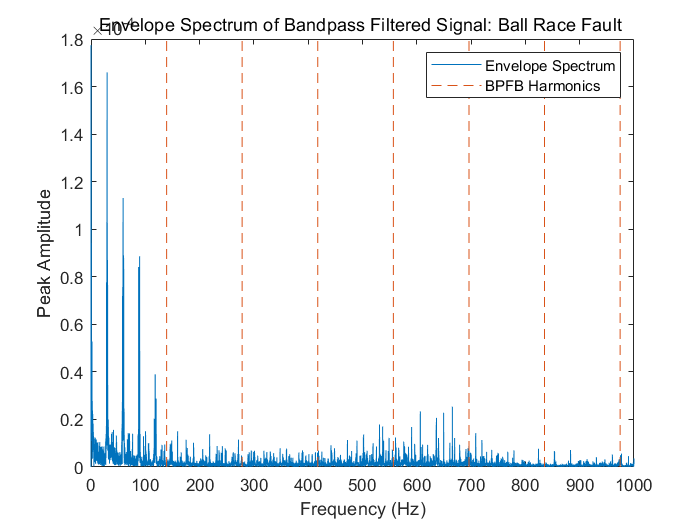

figure(50)

plot(fEnvBallBpf, pEnvBallBpf);
ncomb = 10;
helperPlotCombs(ncomb, BPFB_freq)
xlim([0 1000])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum of Bandpass Filtered Signal: Ball Race Fault ')
legend('Envelope Spectrum', 'BPFB Harmonics')

It is shown that by bandpass filtering the raw signal with the frequency band suggested by kurtogram and spectral kurtosis, the envelope spectrum analysis is able to reveal the fault signature at BPFO and its harmonics.

## **5. Compare analyzed features for each states**

### **Extract and Analyze Time & Frequency Features**

%% time - Features
normal_time_DE = timeFeatures(X098_DE_time)

normal_time_DE = 1×10 table
      rms         sra         kv         sv        ppv        cf        if       mf        sf         kf    
    ________    ________    ______    ________    ______    ______    ______    _____    ______    _________

    0.066352    0.045547    2.9306    -0.17305    0.6634    5.2129    6.4686    7.594    1.2409    1.512e+05


outer_time_DE  = timeFeatures(X131_DE_time)

outer_time_DE = 1×10 table
      rms        sra       kv         sv        ppv        cf        if        mf        sf        kf  
    _______    _______    _____    ________    ______    ______    ______    ______    ______    ______

    0.59195    0.26626    7.595    0.033401    6.1242    5.2577    8.4927    11.689    1.6153    61.858


inner_time_DE  = timeFeatures(X106_DE_time)

inner_time_DE = 1×10 table
      rms        sra        kv        sv        ppv        cf        if        mf        sf       kf  
    _______    _______    ______    _______    ______    ______    ______    ______    ______    _____

    0.29289    0.16484    5.5423    0.13043    2.9838    5.3973    7.6131    9.5902    1.4105    753.1


ball_time_DE   = timeFeatures(X119_DE_time)

ball_time_DE = 1×10 table
      rms        sra         kv         sv         ppv        cf        if        mf        sf        kf  
    _______    ________    ______    _________    ______    ______    ______    ______    ______    ______

    0.13907    0.094363    2.9638    0.0074533    1.2993    4.7433    5.9312    6.9905    1.2504    7923.7


%% freq - Features
normal_freq_DE = freqFeatures(X098_DE_freq)

normal_freq_DE = 1×3 table
        fc           rmsf          rvf    
    __________    __________    __________

    4.1544e-05    0.00018905    0.00018443


outer_freq_DE  = freqFeatures(X131_DE_freq)

outer_freq_DE = 1×3 table
        fc          rmsf          rvf   
    __________    _________    _________

    0.00083659    0.0033835    0.0032785


inner_freq_DE  = freqFeatures(X106_DE_freq)

inner_freq_DE = 1×3 table
        fc          rmsf         rvf   
    __________    ________    _________

    0.00051092    0.001677    0.0015973


ball_freq_DE   = freqFeatures(X119_DE_freq)

ball_freq_DE = 1×3 table
        fc           rmsf          rvf    
    __________    __________    __________

    0.00026417    0.00079807    0.00075309


Freq_normal_DE = 0 : fs/N_normal_DE : fs/2;
Freq_outer_DE = 0 : fs/N_outer_DE : fs/2;
Freq_inner_DE = 0 : fs/N_inner_DE : fs/2;
Freq_ball_DE = 0 : fs/N_ball_DE : fs/2;

###     Time Domain,

        1) Mean 

             - Each values are simillar. Therefore, It is not a significant characteristic in fault diagnosis analysis.

        2) Standard Deviation

             - Unlike normal cases, the standard deviation value in the case of defects increased from as little as 7 times to as much as 30 times. It is presumed that a plurality of outliers are generated in the signal due to noise caused by the occurrence of defects.

        3) RMS $\left(X_{rms} =\sqrt{\frac{1}{N}\ \sum x_i^2 }\right)$

             - The rms value for each case was quite similar to the standard deviation value for each case.

        4) Square Root Average $\left(X_{SRA} ={{\left(\frac{1}{N}\ \sum \sqrt{{\left|x_i \right|}}\right)}}^2 \right)$

             - Unlike normal cases, the SRA value in the case of defects increased from as little as twice to as much as 10 times. It is presumed that a plurality of outliers are generated in the signal due to noise caused by the occurrence of defects.

        5) Average of Absolute Value

             - Each values are simillar and small. Therefore, It looks like meaningless feature.

        6) Energy $\left(X_E =\ \sum \ {{\left(x\right)}}^2 \right)$

             - Normal and Ball cases are very simillar. However, Inner & Outer, The value of the two cases exploded compared to the normal value.

        7) Peak $\left(\left.X_P =\mathrm{m}\mathrm{a}\mathrm{x}\left({\left|x_i \right|}\right)\right)$

             - The ratio of peak values between cases was very similar to the standard deviation and the ratio between cases formed by rms.

        8) Peak to Peak

             - It was similar to the peak data multiplied by twice.

        9) Impulse Factor $\left(X_{IF} =\frac{X_P }{\frac{1}{N}\sum {\left|x_i \right|}}\right)$

             - It is a factor to find the most prominent value (a factor that greatly affects failures and defects), and although the values are different for each case, there was no particularly prominent value, so it is judged that in this dataset, IF is not a significant feature.

        10) Shape Factor $\left(X_{SF} =\frac{X_{rms} }{\frac{1}{N}\sum {\left|x_i \right|}}\right)$

             - Factors influencing the shape of the graph itself. Each values are simillar. Therefore, It looks like meaningless feature.

        11) Crest Factor $\left(X_{crest} =\frac{X_P }{X_{rms} }\right)$

             - Crest Factor provides an early warning for defects when they first occur. It can be seen that the Crest Factor value in the normal case is the smallest, and the values are large in the order of ball < outer < inner. This value size order was similar to the value size order in other features.

        12) Marginal(Clearance) Factor $\left(X_{MF} =\frac{X_P }{X_{SRA} }\right)$

             - In general, this value has a maximum value in a normal rotating machine. The same goes for this dataset. the normal state has the maximum value, and what is peculiar is that the margin factor has the minimum value in the case of ball defects. 

        13) Skewness

             - A measure of how asymmetric a distribution is compared to a normal distribution. If the absolute value is less than 3, it is judged that it meets the stability standard. Case of this dataset, skewness value does not seem to be a significant feature of fault diagnosis analysis because the skewness value in all cases has very small values.

        14) Kurtosis

             - A measure of the sharpness of the frequency distribution. The closer the sample score is to the mean, the sharper the vertex of the distribution, and the farther the sample score is to the mean, the more gentle the vertex of the distribution. The Kurtosis value order in this dataset is the same as the Crest Factor value size order. That is, it can be seen that the more noise and instability there is, the sharper the graph is drawn.

####   To Sum Up,

            - Compared to the normal state, it was confirmed that the values splashed when the failure occurred. In general, the values bounced in the order of outer > inner > ball, and accordingly, it was confirmed that the average value of the overall characteristic data and the values showing the characteristics of the variance increased.

            - It was found that data analysis in the T domain alone could sufficiently determine the presence or absence of simple failure.

###     In Frequency Domain,

        1) Frequency Center $\left(X_{fc} =\frac{1}{N}\sum_{i=1}^N f_i \right)$

             - In the case of the ball, it was seen that it decreased from the normal frequency, and in the other case, it increased from the normal frequency.

        2) RMS(Root Mean Square) $\left(X_{rmsf} ={{\left(\frac{1}{N}\sum_{i=1}^N f_i^2 \right)}}^{\frac{1}{2}} \right)$

             - If there is a defect, a large number of abnormal frequencies are detected, and accordingly, the RMS value seems to have increased as the magnitude of the abnormal frequencies is reflected.

        3) RVF(Root Variance Frequency) $\left(X_{rvf} ={{\left(\frac{1}{N}\sum_{i=1}^N {{\left(f_i -X_{fc} \right)}}^2 \right)}}^{\frac{1}{2}} \right)$

             - Overall, more outliers were detected compared to the steady-state frequency. Focusing on the average, it can be seen that a large number of abnormal frequencies have been detected.

####     To Sum Up,

            - It can be roughly guessed based on labeled data, but since the value of the data itself is very small, analysis through the frequency domain seems to need a newer approach.

### Raw Signal Analysis

- **FFT**

                Unlike the frequency of the normal data was mainly distributed between 0 and 1000Hz,

                the rest fault datasets showed that a large number of frequencies were formed around 3000Hz.

- **PSD**

                The results were all similar. It is estimated that it is not a significant analysis for fault diagnosis.

### Enveloped Signal Analysis

- **FFT**

                In the case of normal data, it was not much different from before Envelop was applied.

                On the other hand, in the case of the Outer case, it was confirmed that a large number of frequencies were mainly distributed between 0 and 1000Hz.

                In the case of the inner case, it was confirmed that one peak value rises in a low frequency band and then distributed little by little to 2,000 Hz.

                In the case of the ball data, it was confirmed that the ball data is distributed little by little between 0 and 1000Hz.

- **PSD**

                The results were all similar. It is estimated that it is not a significant analysis for fault diagnosis.

- **Envelope Spectrum**

                In the case of the normal data, no defect frequency was detected.

                On the other hand, in the case of the Outer case, it was detected defect frequency(BPFO).

                Inner case also detected defect frequency(BPFI).

                However, the defect frequency(BPFB) was not detected in the ball case.

### STFT of given signal

        In all four cases, the frequency change over time was not noticeable. Therefore, it seems to be a meaningless analysis for fault diagnosis.

### Kurtogram & Spectral Kurtosis

        Except for the outer dataset, before apply bandpass filter application, it was confirmed that all three datasets were within the confidence interval.

        Therefore, it is presumed that Kurtosis is not a significant analysis factor for fault diagnosis before apply bandpass filter application except for the outer dataset.

### Signal Analysis after BandPass Filter Application

        1) Normal

             - kurtosis was decreased. (2.9306 -> 2.6449)

             - Most frequencies are distributed between 0 and 100 Hz.

        2) Outer

             - kurtosis was increased. (7.595 -> 8.7827)

             - BPFO is visible, but the peak decreases.

        3) Inner

             - kurtosis was slightly increased. (5.5423 -> 5.5462)

             - BPFI is visible, but the peak decreases.

        4) Ball

             - kurtosis was increased. (2.938 -> 4.819)

             - BPFB is not visible, and fundamental frequency and harmonics of apporximately 29Hz are clearly visible.

        To sum up, if the bearing was defected, kurtosis will be large.

## Conclusion

            - Data for machine learning was collected and refined. 

            - It seems that a failure diagnosis model with sufficient accuracy can be created even if only features extracted from Time Domain are used.

            - In addition, it seems desirable to use kurtosis data & Envelope Spectrum data to classify the type of failure of the bearing.